# Download the dataset

First, we download previously generated training (through simulation) and test (from a real robot) dataset. The dataset should be first downloaded and unzipped into a local subdirectory called `dataset`. In `dataset/`, you will find three subfolders:

- trainingDatasets: Contain the training data;

- testDatasetsOriginal: Contain the test data in the original format collected from the robot

- testDatasets: Contain the test data transformed into the Matlab format.

- dataset_descrpitions.txt: Describe the settings for generating each training and test dataset.

You can either download the dataset from [this link](http://%27https//nextcloud.centralesupelec.fr/s/7AR6aamBZNXcRM8/download'). Then, you should unzip the downloaded file and put the folder `dataset under the root dictionary. Or you can directly run this code to download the dataset. Depending on the network condition, it migth take up to 20 mins to download the dataset.`

url = 'https://nextcloud.centralesupelec.fr/s/7AR6aamBZNXcRM8/download';
downloadFolder = fullfile('../', 'dataset');
rootDict = fullfile('../');
if ~exist(downloadFolder, 'dir')
    options = weboptions('Timeout', 30);
    loc = websave([downloadFolder '.zip'], url, options);
    unzip(loc, rootDict);
end

# Data preparation

## Load the training data

In this study, we train and test a fault diagnosis model both using the simulated failure data. First, we load the original training dataset, and create two cell arrays:

- dataTables: A cellarray of 3600 elements, each element is a dataTable, contains all the available features.

- y: A cellarray of 3600 elements, each element is the label (str).

clear; clc; close all;
warning('off');

% Set random seed for reproduction purpose.
rng(10);

doTraining = true;
trainingDataFolderName = '20241017';

% File to save the trained model.
mdlName = ['mdlMotorCmdsTrajResps' 'TrData' trainingDataFolderName 'TestDataSim' '.mat'];

% Define the path to check for 'conc_dataset.mat'
pathLoggedTrainingData = ['../dataset/trainingDatasets/' trainingDataFolderName '/training_dataset.mat'];
pathTrainingData = ['../dataset/trainingDatasets/' trainingDataFolderName '/'];


% Define a DataLoader instance.
% Define the length of simulation and the corresponding sequence length.
lenSeries = 1000; % Sequence length.
simulationTime = 10; % The time that this sequence corresponds to.
dataLoader = DataLoader(lenSeries, simulationTime);
dataLoader.pathTrainingDataset = pathTrainingData;
dataLoader.pathLoggedTrainingData = pathLoggedTrainingData;
[dataTables, y] = dataLoader.loadTrainingData();

Loaded data from ../dataset/trainingDatasets/20241017/training_dataset.mat


We can print an example of all the features. It should be noted that the features Motor1Cmd - Motor5Cmd and RealizedTrajectory-x, RealizedTrajectory-y and RealizedTrajectory-z are original data directly observed. The features DesiredTrajectory-x, y, z are auxilarry features calculated based on a digital twin simulation using Motor1Cmd - Motor5Cmd.

dataTables{1}

ans = 1000×13 table
    Timestamps    Motor1Cmd    Motor2Cmd     Motor3Cmd      Motor4Cmd     Motor5Cmd    DesiredTrajectory-x    DesiredTrajectory-y    DesiredTrajectory-z    RealizedTrajectory-x    RealizedTrajectory-y    RealizedTrajectory-z                             matFilePath                          
    __________    _________    _________    ___________    ___________    _________    ___________________    ___________________    ___________________    ____________________    ____________________    ____________________    ____________________________

## Training and validation set creation

We randomly split a dataset and train a LSTM.

% Shuffle the dataset using the cvpartition function
training_ratio = .9;
n_dataset = numel(dataTables);
training_size = floor(training_ratio*n_dataset);
cvObj = cvpartition(y, 'HoldOut', training_size);
idx = cvObj.test;

% Split into training and test data based on training size specified
dataTables_X_train = dataTables(idx');
dataTables_X_test = dataTables(~idx');
y_train = categorical(y(idx'));
y_test = categorical(y(~idx'));

We can show the distribution of classes in the training and testing dataset, to make sure the seperation is fair.

summary(y_train);

     Healthy      Motor_1_Steady_state_error      Motor_1_Stuck      Motor_2_Steady_state_error      Motor_2_Stuck      Motor_3_Steady_state_error      Motor_3_Stuck      Motor_4_Steady_state_error      Motor_4_Stuck 
     360          360                             360                360                             360                360                             360                360                             360           


summary(y_test);

     Healthy      Motor_1_Steady_state_error      Motor_1_Stuck      Motor_2_Steady_state_error      Motor_2_Stuck      Motor_3_Steady_state_error      Motor_3_Stuck      Motor_4_Steady_state_error      Motor_4_Stuck 
     40           40                              40                 40                              40                 40                              40                 40                              40            


# Pre-processing and feature engineering

First, we try to use only the directly observed features, i.e., the motor commands, and the observed end-effector trajectory (x, y, z). We standardize each feature for better training performance.

X_train = dataLoader.extractFeaturesOriginal(dataTables_X_train);
X_test = dataLoader.extractFeaturesOriginal(dataTables_X_test);

[X_train, M, S] = normalize_features(X_train);
[X_test, ~, ~] = normalize_features(X_test, M, S);

# Training and evaluating the model

Use an LSTM network. An LSTM layer learns long-term dependencies between time steps of time series or sequence data. The first lstmlayer will have 100 hidden units and output the sequence data. Then a dropout layer will be used to reduce probability of overfitting. The second lstmlayer will output just the last step of the time sequence.

layers = [ ...
    sequenceInputLayer(size(X_train{1},1))
    lstmLayer(100,"OutputMode","sequence")
    dropoutLayer(0.1)
    lstmLayer(100,"OutputMode","last")
    fullyConnectedLayer(numel(categories(y_train)))
    softmaxLayer
    classificationLayer];

## Define Network Hyperparameters

miniBatchSize = 32;
validationFrequency = floor(numel(X_train)/miniBatchSize);
options = trainingOptions("adam", ...
    "MaxEpochs",30, ...
    "MiniBatchSize",miniBatchSize, ...
    "Plots","training-progress", ...
    "Verbose",false, ...
    "Shuffle","every-epoch", ...
    "LearnRateSchedule","piecewise", ...
    "LearnRateDropFactor",0.1, ...
    "LearnRateDropPeriod",20,...
    'ValidationData',{X_test, y_test}, ...
    'ValidationFrequency',validationFrequency);

## Train The Network

This network takes about 100 seconds to train on an NVIDIA RTX 2080 GPU.

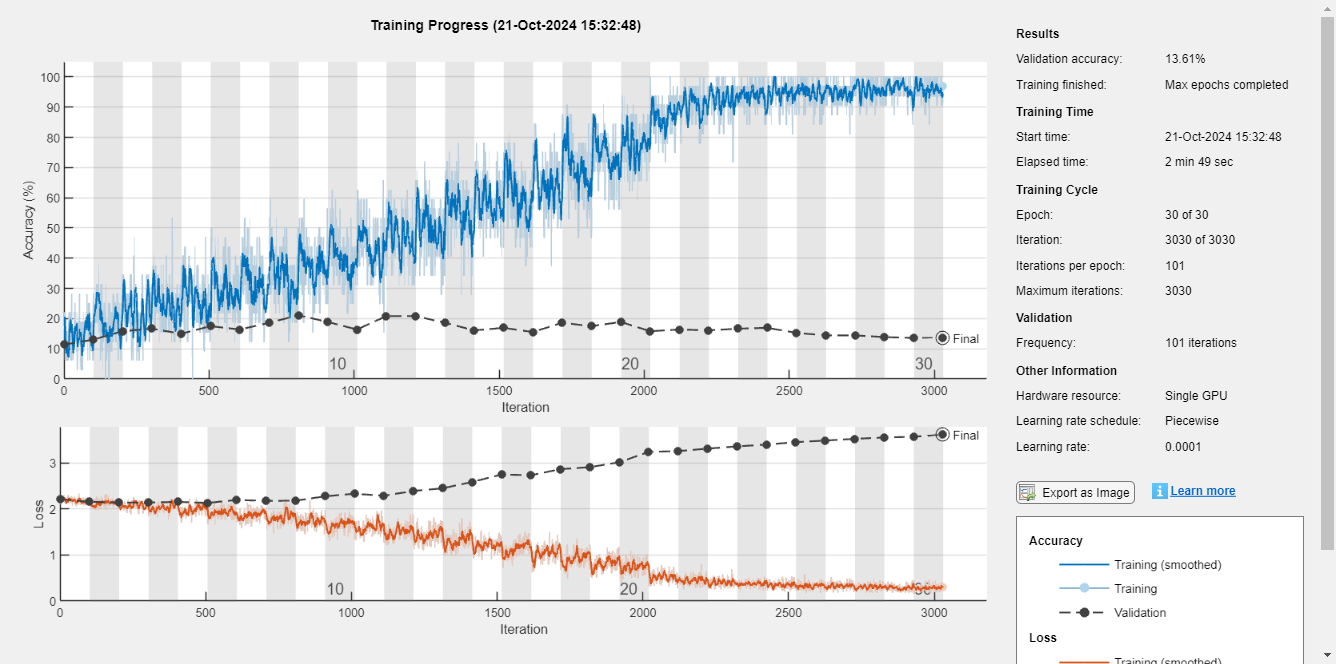

if doTraining
    diagnosisNet = trainNetwork(X_train, y_train, layers, options);
    save(mdlName, 'diagnosisNet');
else
    load(mdlName, 'diagnosisNet');
end

## Test The Network

Now that the network has been trained, we can test it on the validation data. 

y_pred = classify(diagnosisNet, X_test);

View the confusion chart for the test results:

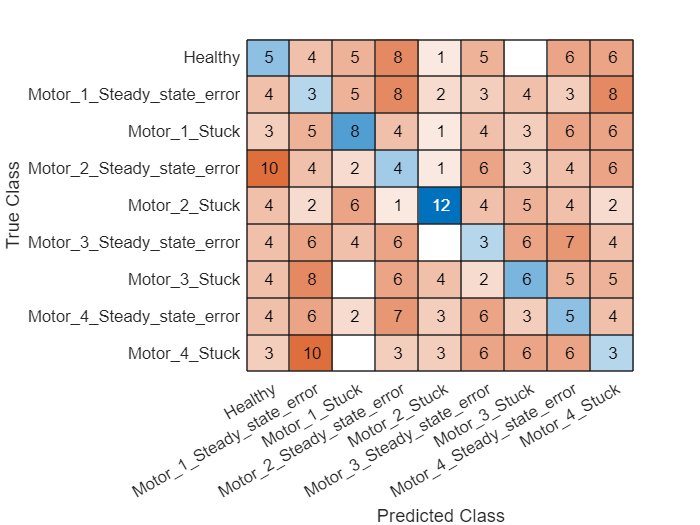

cm = confusionchart(y_test', y_pred);

View the overall accuracy percentage of the validation and test results:

[accuracy, precision, recall, f1Score] = dataLoader.evalPerf(y_test, y_pred);
% Display the results
fprintf('Overall Accuracy: %.2f%%\n', accuracy * 100);

Overall Accuracy: 13.61%


class_names = categories(y_test);
for i = 1:numel(class_names)
    fprintf('Class %d (%s): Precision = %.2f, Recall = %.2f, F1 Score = %.2f\n', i, class_names{i}, precision(i), recall(i), f1Score(i));
end

Class 1 (Healthy): Precision = 0.12, Recall = 0.12, F1 Score = 0.12
Class 2 (Motor_1_Steady_state_error): Precision = 0.06, Recall = 0.07, F1 Score = 0.07
Class 3 (Motor_1_Stuck): Precision = 0.25, Recall = 0.20, F1 Score = 0.22
Class 4 (Motor_2_Steady_state_error): Precision = 0.09, Recall = 0.10, F1 Score = 0.09
Class 5 (Motor_2_Stuck): Precision = 0.44, Recall = 0.30, F1 Score = 0.36
Class 6 (Motor_3_Steady_state_error): Precision = 0.08, Recall = 0.07, F1 Score = 0.08
Class 7 (Motor_3_Stuck): Precision = 0.17, Recall = 0.15, F1 Score = 0.16
Class 8 (Motor_4_Steady_state_error): Precision = 0.11, Recall = 0.12, F1 Score = 0.12
Class 9 (Motor_4_Stuck): Precision = 0.07, Recall = 0.07, F1 Score = 0.07


### Summary of the results

From the results, we can see that if we only use the original features, the model fails to achieve good performance on the validation dataset, even through the performance on the training data is good. This is because what we observed is the response on the system-level (trajectory of the end-effector), but what we want to predict is the failure mode on the component (motor) level. This experiment shows that without the help of the digital twin, this diagnosis task is difficult for a traditional deep learning model.

# Use the digital twin to augument the features

Now we use the digital twin to create some auxiliary features. First, we use the digital twin model to simulate the desired trajectory from the commands of the four motors. Then, we calculate the residuals between the response and desired trajectory on the x, y and z axis. The desired trajectories (x, y and z) and the residuals of trajectories (x, y and z) are then used to compose a new feature space (with 6 dimensions).

% Add an additional feature of the residual.
mdlName = ['mdlTrajCmdsTrajResps' 'TrData' trainingDataFolderName 'TestDataSim' '.mat'];

X_train = dataLoader.extractFeaturesTrajCmdTrajResidual(dataTables_X_train);
X_test = dataLoader.extractFeaturesTrajCmdTrajResidual(dataTables_X_test);

[X_train, M, S] = normalize_features(X_train);
[X_test, ~, ~] = normalize_features(X_test, M, S);

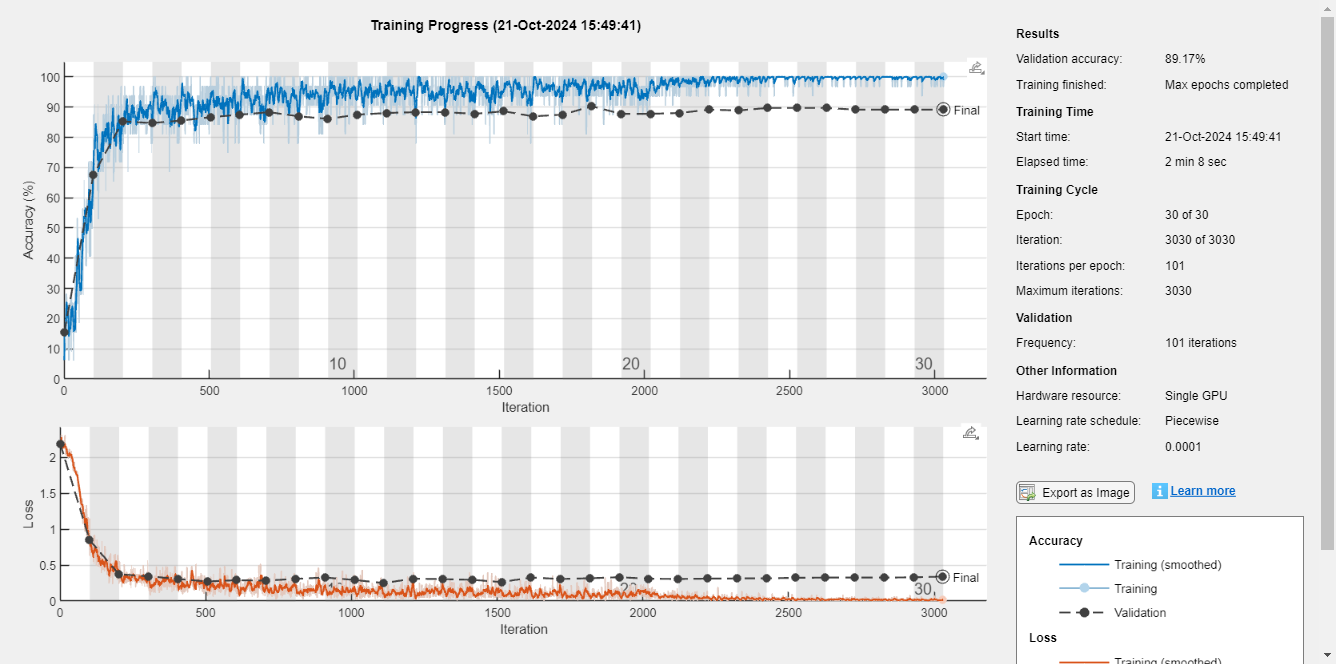

layers = [ ...
    sequenceInputLayer(size(X_train{1},1))
    lstmLayer(100,"OutputMode","sequence")
    dropoutLayer(0.1)
    lstmLayer(100,"OutputMode","last")
    fullyConnectedLayer(numel(categories(y_train)))
    softmaxLayer
    classificationLayer];

miniBatchSize = 32;
validationFrequency = floor(numel(X_train)/miniBatchSize);
options = trainingOptions("adam", ...
    "MaxEpochs",30, ...
    "MiniBatchSize",miniBatchSize, ...
    "Plots","training-progress", ...
    "Verbose",false, ...
    "Shuffle","every-epoch", ...
    "LearnRateSchedule","piecewise", ...
    "LearnRateDropFactor",0.1, ...
    "LearnRateDropPeriod",20,...
    'ValidationData',{X_test, y_test}, ...
    'ValidationFrequency',validationFrequency);

if doTraining
    diagnosisNet = trainNetwork(X_train, y_train, layers, options);
    save(mdlName, 'diagnosisNet');
else
    load(mdlName, 'diagnosisNet');
end

y_pred = classify(diagnosisNet, X_test);

View the confusion chart for the test results:

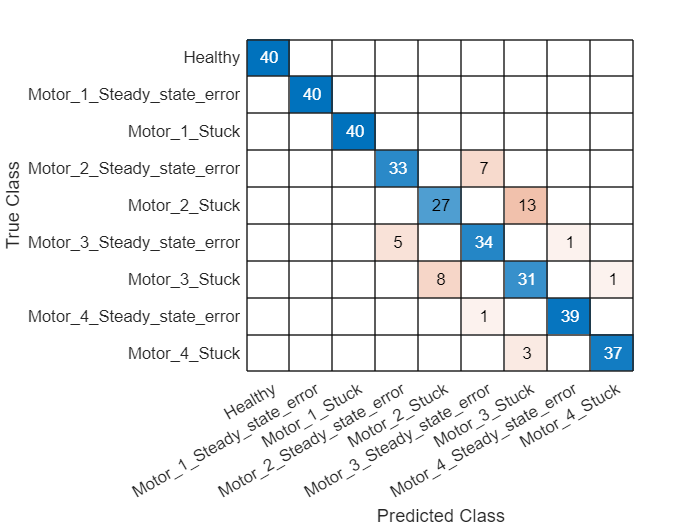

cm = confusionchart(y_test', y_pred);

View the overall accuracy percentage of the validation and test results:

[accuracy, precision, recall, f1Score] = dataLoader.evalPerf(y_test, y_pred);
% Display the results
fprintf('Overall Accuracy: %.2f%%\n', accuracy * 100);

Overall Accuracy: 89.17%


class_names = categories(y_test);
for i = 1:numel(class_names)
    fprintf('Class %d (%s): Precision = %.2f, Recall = %.2f, F1 Score = %.2f\n', i, class_names{i}, precision(i), recall(i), f1Score(i));
end

Class 1 (Healthy): Precision = 1.00, Recall = 1.00, F1 Score = 1.00
Class 2 (Motor_1_Steady_state_error): Precision = 1.00, Recall = 1.00, F1 Score = 1.00
Class 3 (Motor_1_Stuck): Precision = 1.00, Recall = 1.00, F1 Score = 1.00
Class 4 (Motor_2_Steady_state_error): Precision = 0.87, Recall = 0.82, F1 Score = 0.85
Class 5 (Motor_2_Stuck): Precision = 0.77, Recall = 0.68, F1 Score = 0.72
Class 6 (Motor_3_Steady_state_error): Precision = 0.81, Recall = 0.85, F1 Score = 0.83
Class 7 (Motor_3_Stuck): Precision = 0.66, Recall = 0.78, F1 Score = 0.71
Class 8 (Motor_4_Steady_state_error): Precision = 0.97, Recall = 0.97, F1 Score = 0.97
Class 9 (Motor_4_Stuck): Precision = 0.97, Recall = 0.93, F1 Score = 0.95


### Summary and discussions

It can be seen that after using the digital twin to complement features, the fault diagnosis model can perform well on the validation set. 

The only two failure modes that the model does not perform well is the stuck of motors 2 and 3. This is because these two motors are nearby and sometimes the response on the trajectory levels are similar for both failure modes.

# Supporting functions

function [X, M, S] = normalize_features(X, M, S)
    % This function normalizes the features.
    % Input: X is an cell array of 1*n_data, whose elements are matrixs of
    % (n_seq, n_features).

    if nargin == 1
        % Concatenate all the features. Creat a matrix of (n_seq*n_data,
        % n_features).
        allFeatures = cat(1, X{:});
    
        % Do the normalization.
        M = mean(allFeatures);
        S = std(allFeatures);
    end
    
    for index = 1:numel(X)
       X{index} =  ((X{index} - M)./S);
    end
end